clear;
close all;
clc;

1) Load data

path='data\SRAS\Task 1\Task_1_ref_waveform.mat';
load(path);

velocity = 2933; % m/s, as given.

2) Plot and find the central frequency

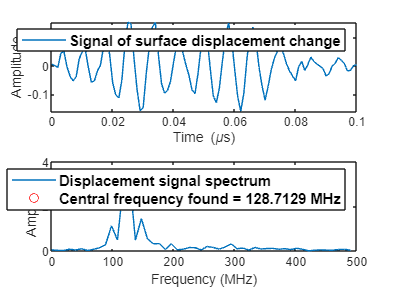

sig = tmptrc;
t = xscale;

% Plot the raw signal to see the orignal data
figure;
subplot(2,1,1)
plot(t*1e6,sig);
xlabel('Time (\mus)');
ylabel('Amplitude');
axis tight;
legend('Signal of surface displacement change','Location','northeast', ...
    'Fontweight','bold', ...
    'Fontsize',10)


dt = t(2)-t(1);
fs = 1/dt;                      % sginal's sampling frequency, in replace of the fscale
pts = 2*ceil(length(t)/2);

spectrum = abs(fft(sig,pts)); 
spectrum = spectrum(1:pts/2);
f=fs*(0:(pts/2-1))/pts;         % discard the mirror image

% Find and label the center frequency
[fcspec,idx] = max(spectrum);
fc = fscale(idx);

% plot scripts
subplot(2,1,2)
plot(f*1e-6,spectrum); hold on;
xlabel('Frequency (MHz)');
ylabel('Amplitude');
plot(fc*1e-6,spectrum(idx),'ro');
str = ['Central frequency found = ',num2str(fc*1e-6),' MHz'];
legend('Displacement signal spectrum',str,'Fontweight','bold','Fontsize',10);

3) Compute wavelength and selecting patch size based on the illustration.

lambda = velocity/fc * 1e3;
fprintf(['wavelength \x03bb = v/fc = ',num2str(lambda),' mm'])

wavelength λ = v/fc = 0.022787 mm